## **Integrations**

Electric Potential and Electric Field

- 1D, Line Charge:

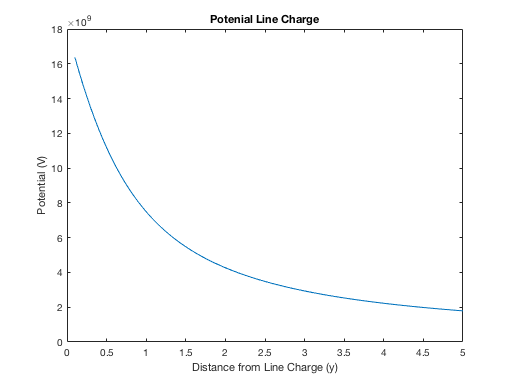

epsilon_0 = 8.8*10.^-12;
C = 1./(4*pi*epsilon_0);
y = linspace(.1,5,100);
f = @(x,y) (2*x*C)./sqrt(x.^2+y.^2);
V = zeros(1,100);

for i=1:100
    dy=y(i);
    x=linspace(0,1,100); %integral dx' from 0 to 1
    v=integral(@(x)f(x,dy),0,1);
    V(i)=v;
end

plot(y,V);
title('Potenial Line Charge');
xlabel('Distance from Line Charge (y)');
ylabel('Potential (V)');

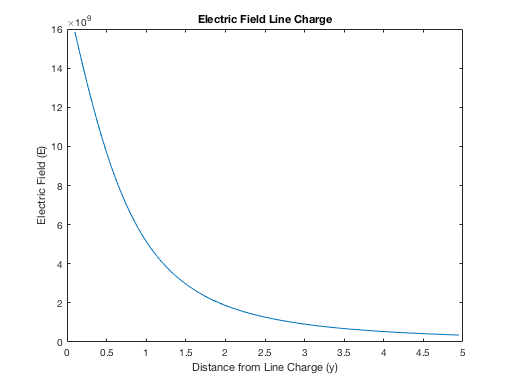


[E,Y] = Der(-V,y,'cd');

plot(Y,E);
title('Electric Field Line Charge');
xlabel('Distance from Line Charge (y)');
ylabel('Electric Field (E)');

- 2D, Two Line Charges:

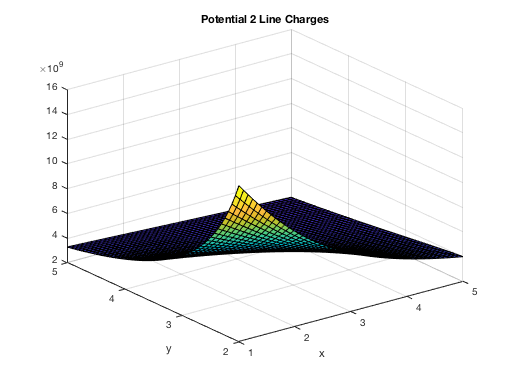

y1 = linspace(2,5,50);
x1 = linspace(1,5,50);
f1 = @(x2,y1,x1) (C*x2.^2)./(sqrt(x1-x2).^2+(y1-1).^2);
f2 = @(y2,x1,y1) y2*C./sqrt(x1.^2+(y1-y2).^2);

V_2D = zeros(50,50);

for i=1:50
    for j=1:50
        dx2=x1(i);
        dy2=y1(j);
        x2=linspace(0,1,50); %integral dx' from 0 to 1
        y2=linspace(1,2,50); %integral dy' from 1 to 2
        v1=integral(@(x2)f1(x2,dy2,dx2),0,1);
        v2=integral(@(y2)f2(y2,dx2,dy2),1,2);
        V_2D(i,j)=v1+v2;
    end
end

surf(x1,y1,V_2D)
title('Potential 2 Line Charges');
xlabel('x');
ylabel('y');

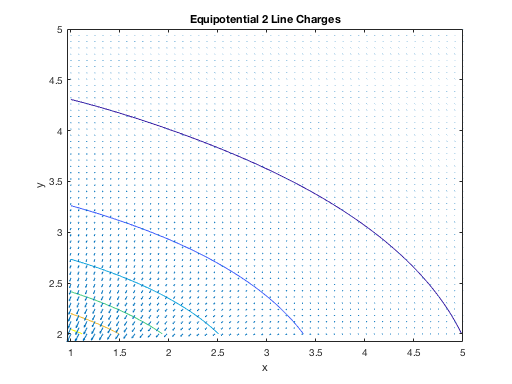

[X2,Y2] = meshgrid(x1,y1);
[DX2,DY2] = gradient(V_2D);

figure
contour(x1,y1,V_2D)
title('Equipotential 2 Line Charges');
xlabel('x');
ylabel('y');
hold on
quiver(X2,Y2,DX2,DY2)
hold off

- 2D, Disk of Charge:

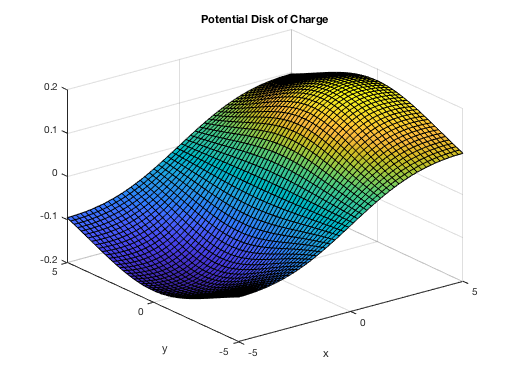

y3 = linspace(-5,5,50);
x3 = linspace(-5,5,50);
f3 = @(r,t,x3,y3) cos(t).*(r.^2)./sqrt((x3-r.*cos(t)).^2 + (y3-r.*sin(t)).^2 + 5.^2); %define at a distance z=5 from the disk

V_disk = zeros(50,50);

for i=1:50
    for j=1:50
        dx3=x3(i);
        dy3=y3(j);
        r=linspace(0,2,50); %integral dr from 0 to 2
        t=linspace(0,2*pi,50); %integral dt from 0 to 2pi
        v_disk=integral2(@(r,t)f3(r,t,dy3,dx3),0,2,0,2*pi);
        V_disk(i,j)=v_disk;
    end
end

surf(x3,y3,V_disk)
title('Potential Disk of Charge');
xlabel('x');
ylabel('y');

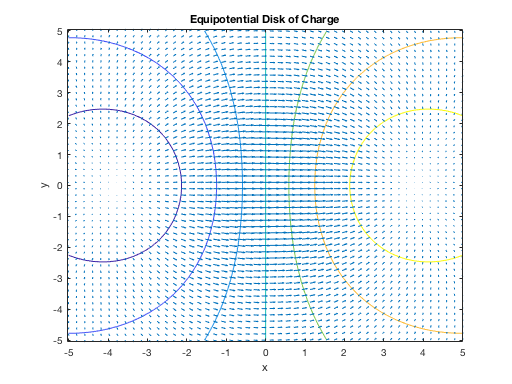

[X3,Y3] = meshgrid(x3,y3);
[DX3,DY3] = gradient(V_disk);

figure
contour(x3,y3,V_disk)
title('Equipotential Disk of Charge');
xlabel('x');
ylabel('y');
hold on
quiver(X3,Y3,DX3,DY3)
hold off